# The displacement vector field $u$

This is a place where we can play with the vector field $u$ and add some other form of noise to the data.

## 1    The crystal lattice

For reference, shown here is an undistorted crystal lattice (basically a product of sinusoids) produced by substituting $\vec{u}=\vec{0}$ to equation S5 of Lawler-Fujita (2010)'s supplementary material.

Creating the lattice and applying the Fourier transform to the created image.

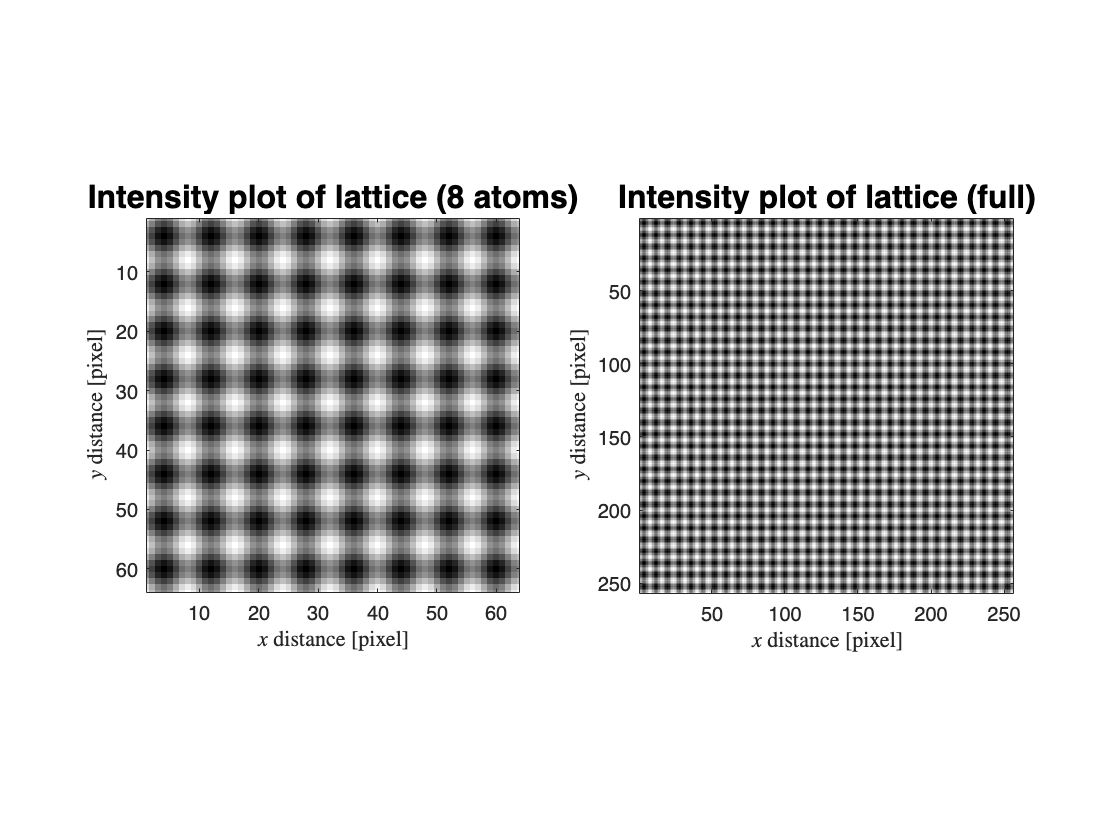

image_length = 256;
image_height = 256;
atom_diameter = 8;

Q_x = [1 0];
Q_y = [-Q_x(2) Q_x(1)]; % just to ensure orthogonality
Q_x = Q_x * 2*pi / (norm(Q_x)*atom_diameter);
Q_y = Q_y * 2*pi / (norm(Q_y)*atom_diameter);

lattice = normies(uTransform(uCreate(image_height,image_length,0) ...
    ,Q_x,Q_y))*atom_diameter/2; % notice the zero
comboPlot(lattice,"lattice",atom_diameter);

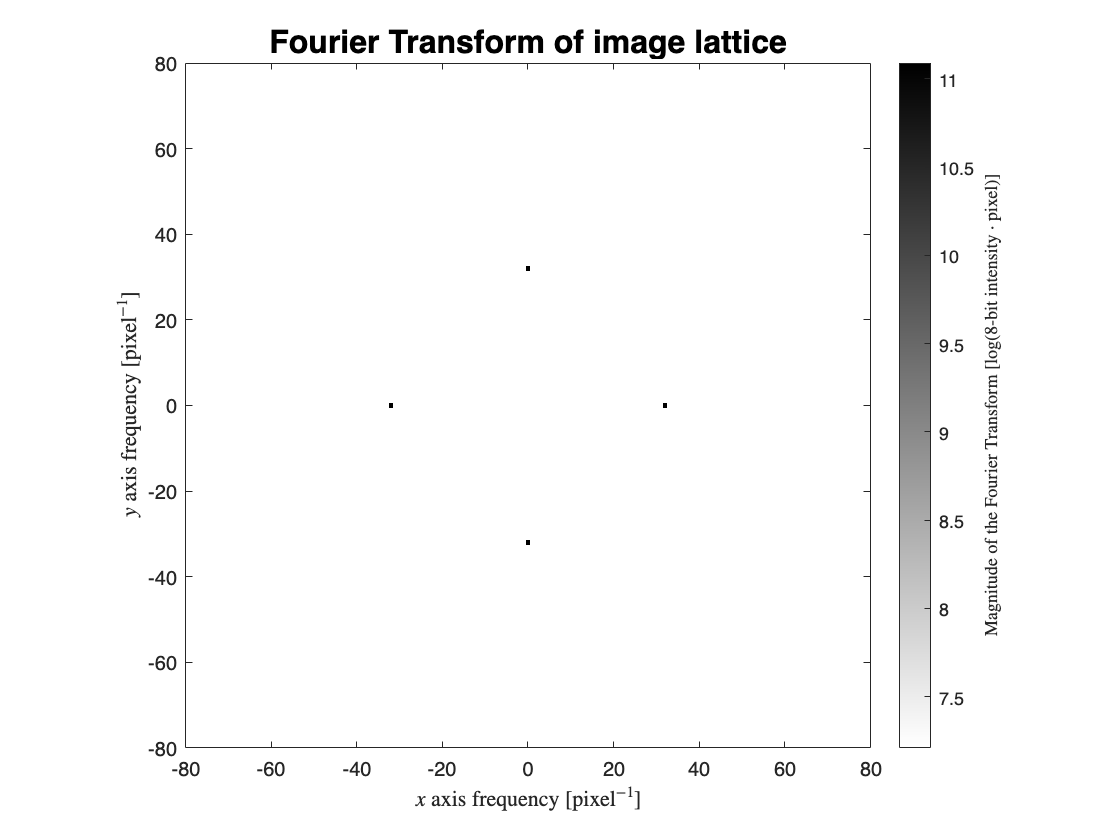

lattice_fft = myFFT(lattice,"lattice");

## 2    A distorted crystal lattice

We create a distorted lattice with the displacement vector [UNSPECIFIED] and apply the Fourier transform to the distorted image.

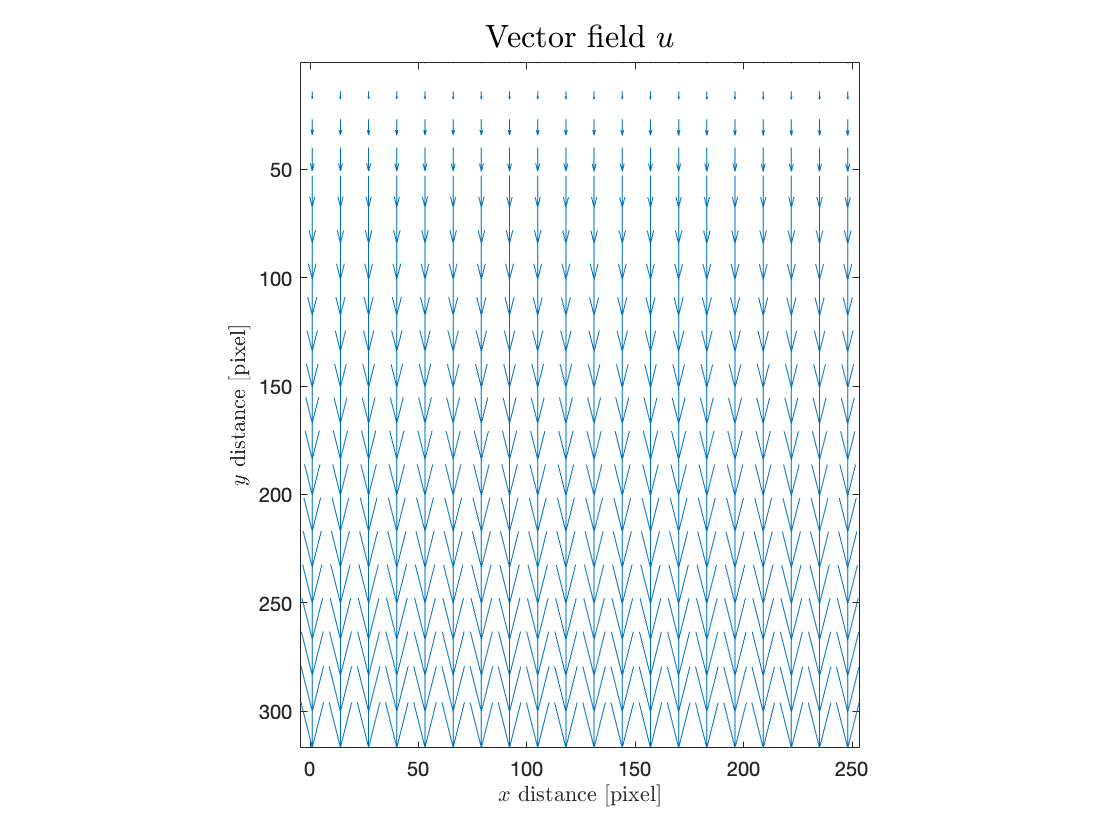

u = uCreate(image_height,image_length,atom_diameter,[0 8.9],[0 0],[0 0]);
% the third parameter specifies the atom diameter
% the first vector is the x,y drift speed [atom diameter per time unit]
% the second vector is the x,y maximum displacement from hysteresis [atom diameter]
% the third vector is the x,y for creep [atom diameter]

uPlot(u,"$u$");

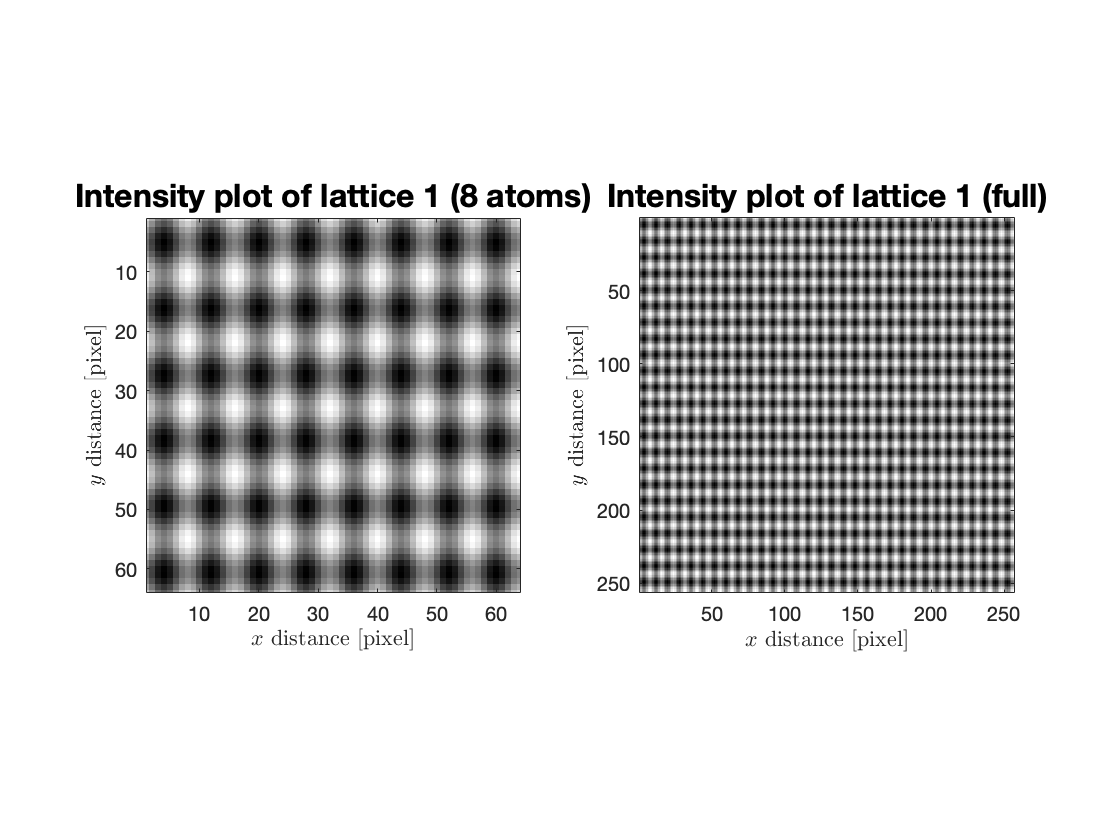


lattice1 = normies(uTransform(u,Q_x,Q_y))*atom_diameter/2;
comboPlot(lattice1,"lattice 1",atom_diameter);

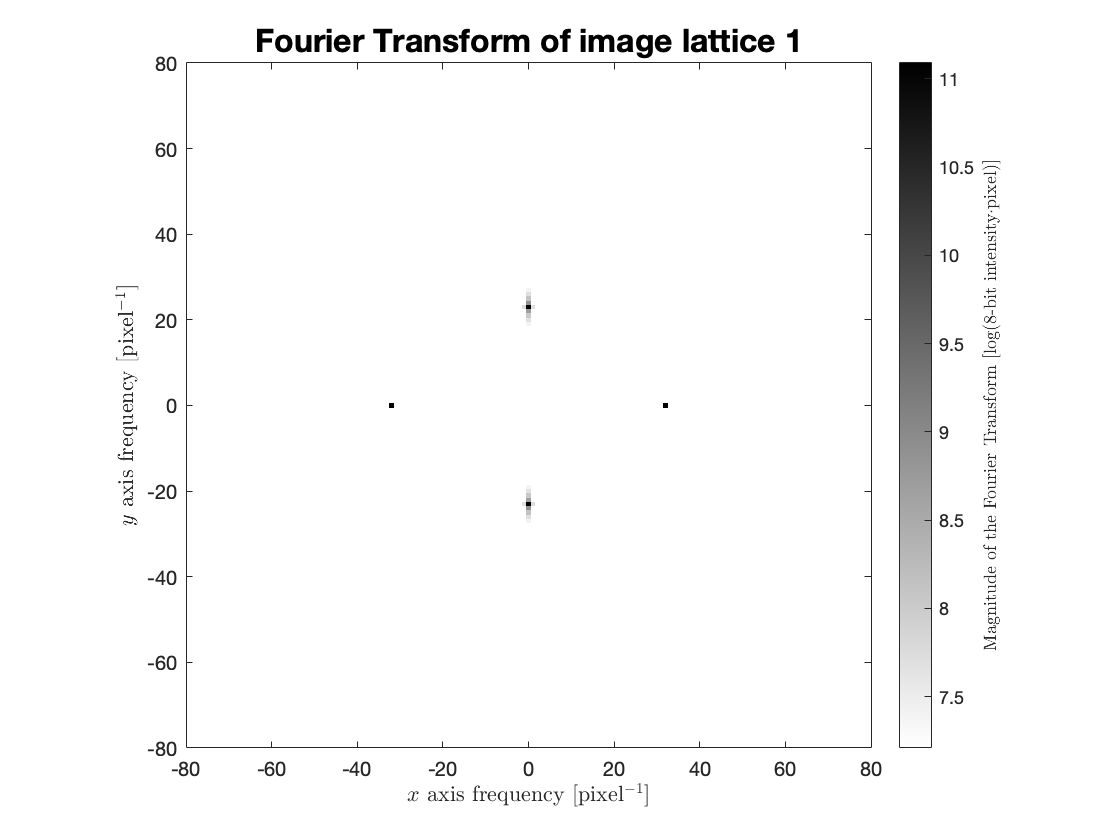


lattice1_fft = myFFT(lattice1,"lattice 1");

## 3    Calculating the vector field $u$

We're going to pretend that we don't know the displacement vector field that resulted to lattice1. Let's calculate $u$ only from the matrix/image lattice1.

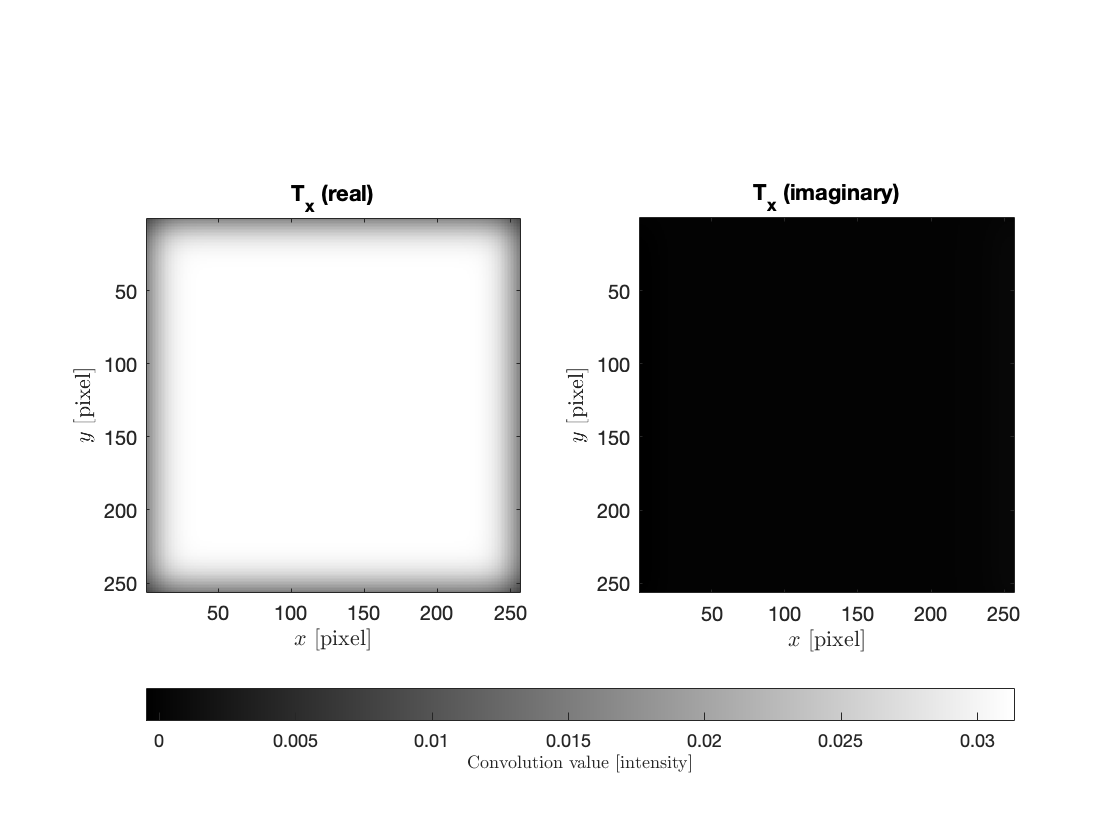

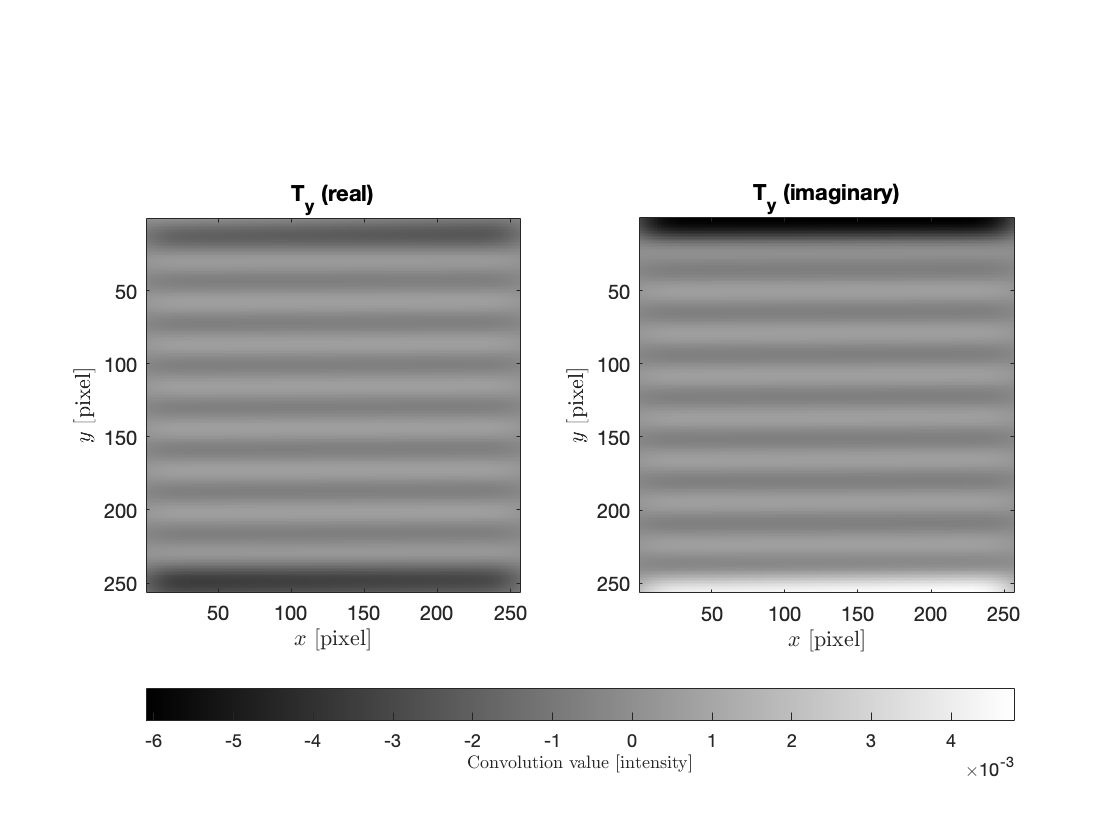

lambda = 0.1; % [rad atom^-1]
lambda = lambda*2*pi/atom_diameter;

tic
ucalc = myConv(lattice1,Q_x,Q_y,lambda);

toc

Elapsed time is 1.292277 seconds.


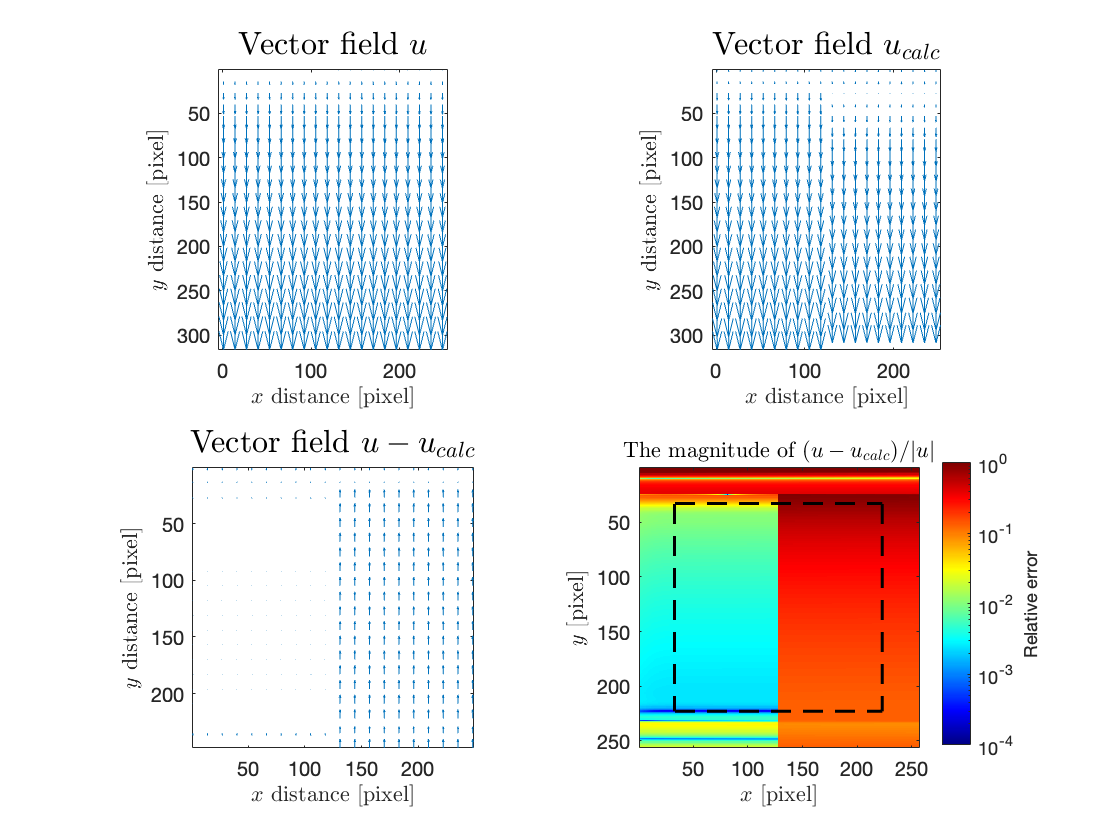


uComboPlot(u,ucalc,lambda);

Notice the wanky edges on the $T_x$ and $T_y$ plots. That's because the convolution function in MatLab padds the matrices with zeros on the edges.

## 4    Adding a random contour as topographic noise

This generates a random but approximately smooth topographic noise by assigning random numbers and then solving the Laplace equation with free boundaries by relaxation. To eliminate unwanted high frequency intensity oscillations, a low-pass filter was employed with a minimum period of [UNSPECIFIED] of the diameter of an atom. The magnitude of the noise can also be adjusted.

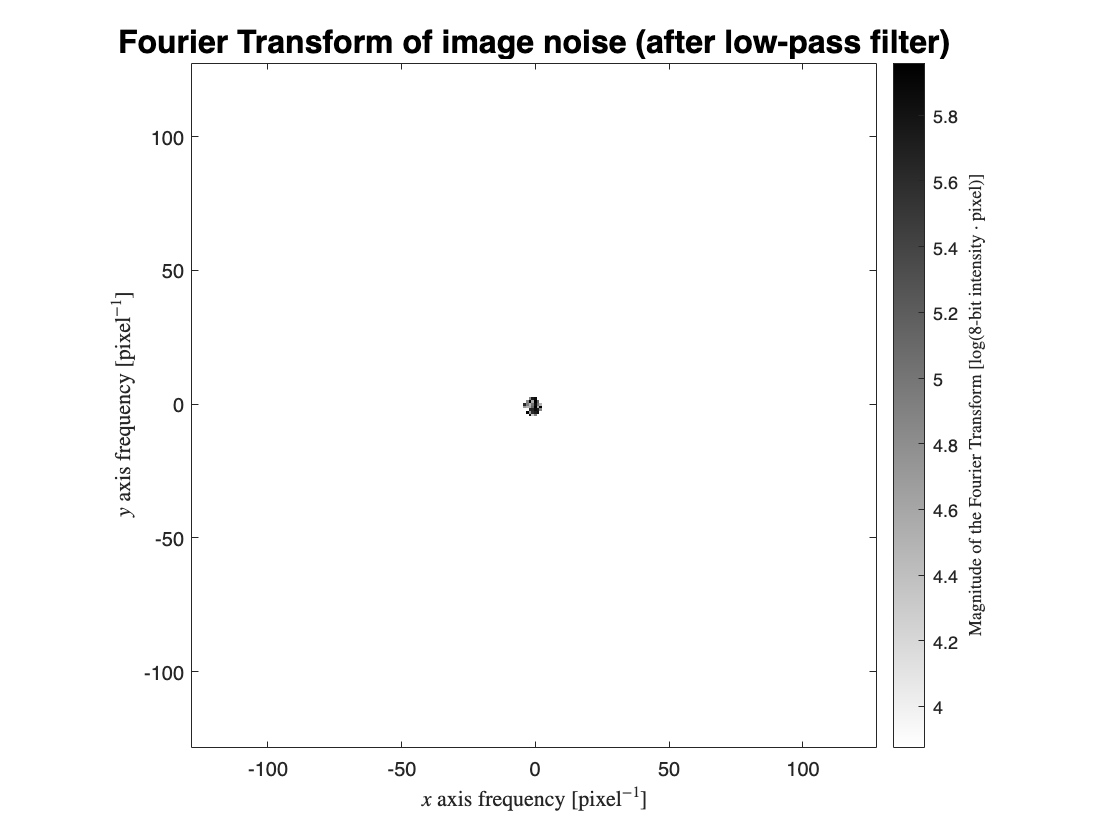

% noise = noiseLaplace(image_height,image_length,atom_diameter);

noise = randn(image_height,image_length);

noise = real(ifft2(myFFT(noise,"noise",[],atom_diameter*10)));

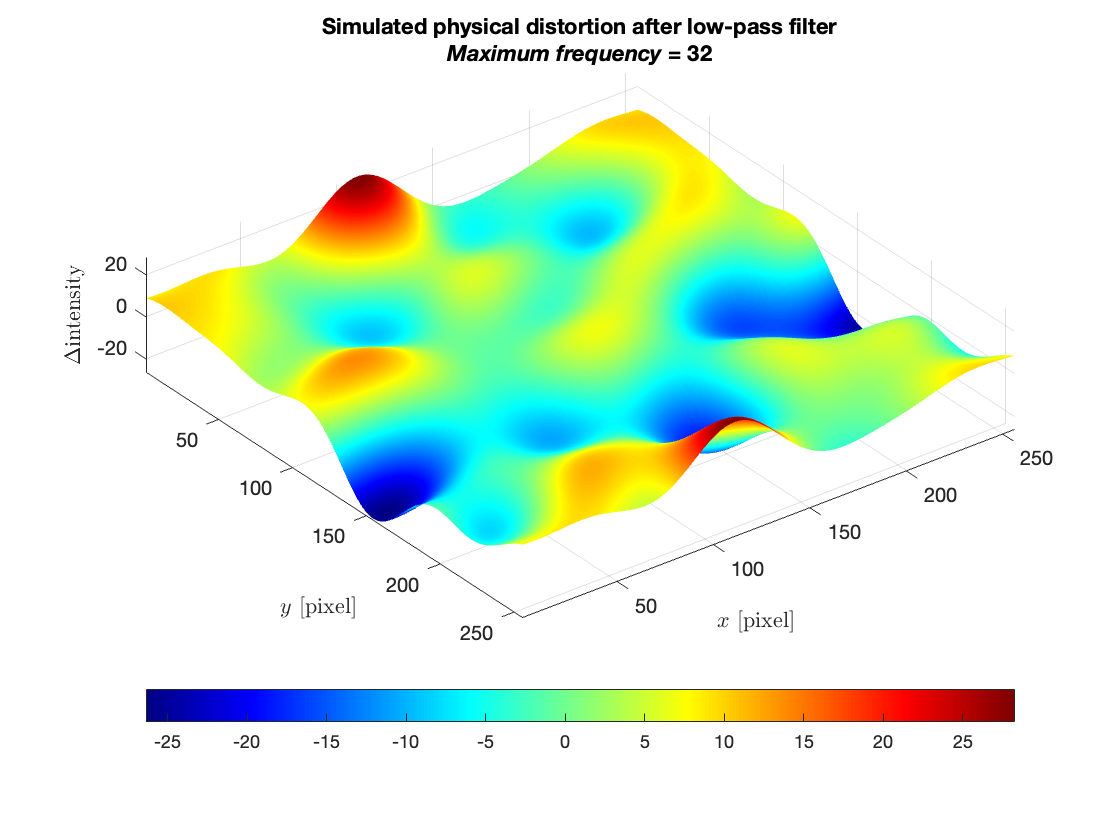

noise = (noise-mean(noise,"all"))/std(noise,1,"all")*atom_diameter;
% one standard deviation of the noise magnitude is the diameter of an atom

noisePlot(image_height,image_length,noise,[],atom_diameter);

Later on, I noticed that the Laplace relaxation step can be skipped — we can start with random numbers and then simply apply the low-pass filter.

Add the noise to a perfect lattice.

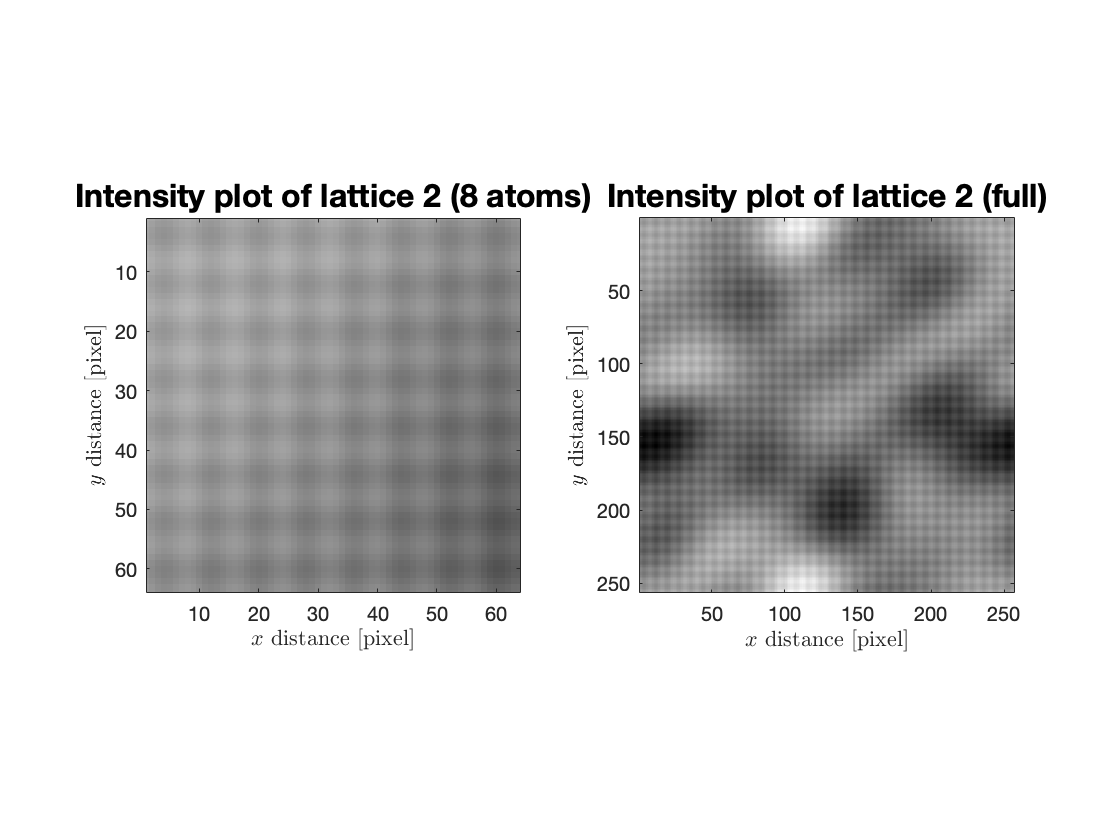

lattice2 = lattice+noise;
comboPlot(lattice2,"lattice 2",atom_diameter);

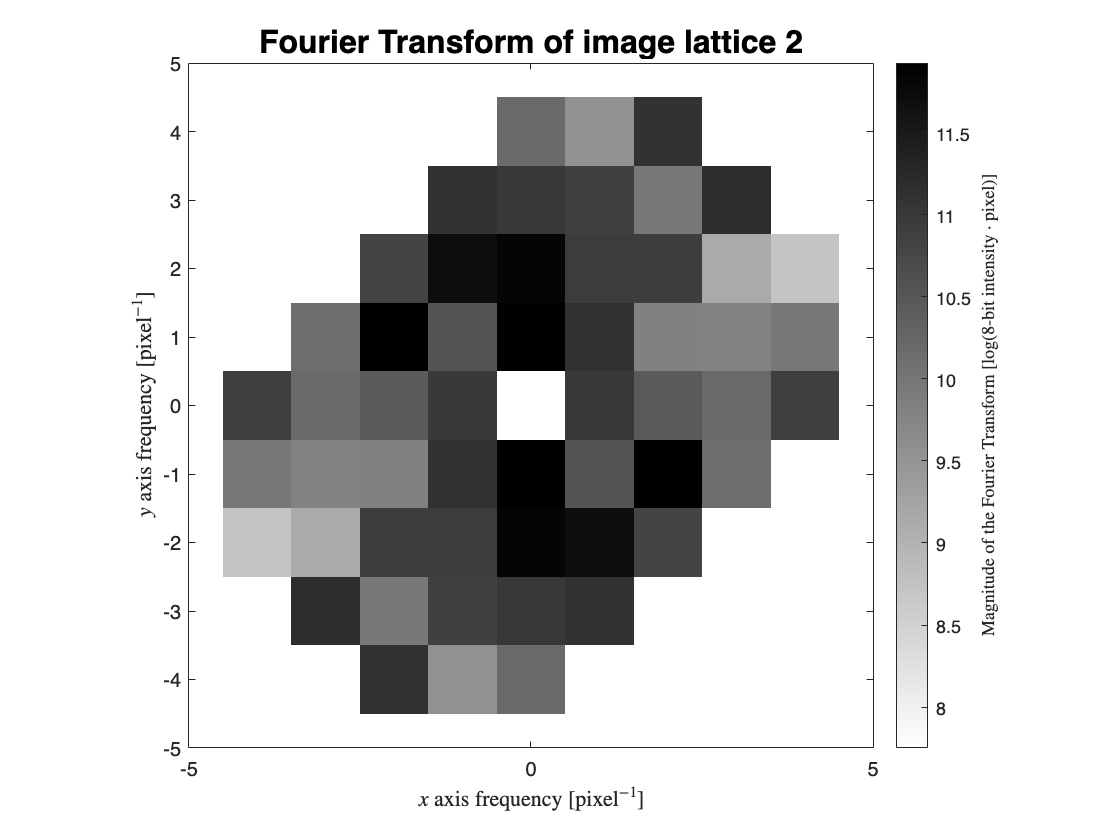

lattice2_fft = myFFT(lattice2,"lattice 2");

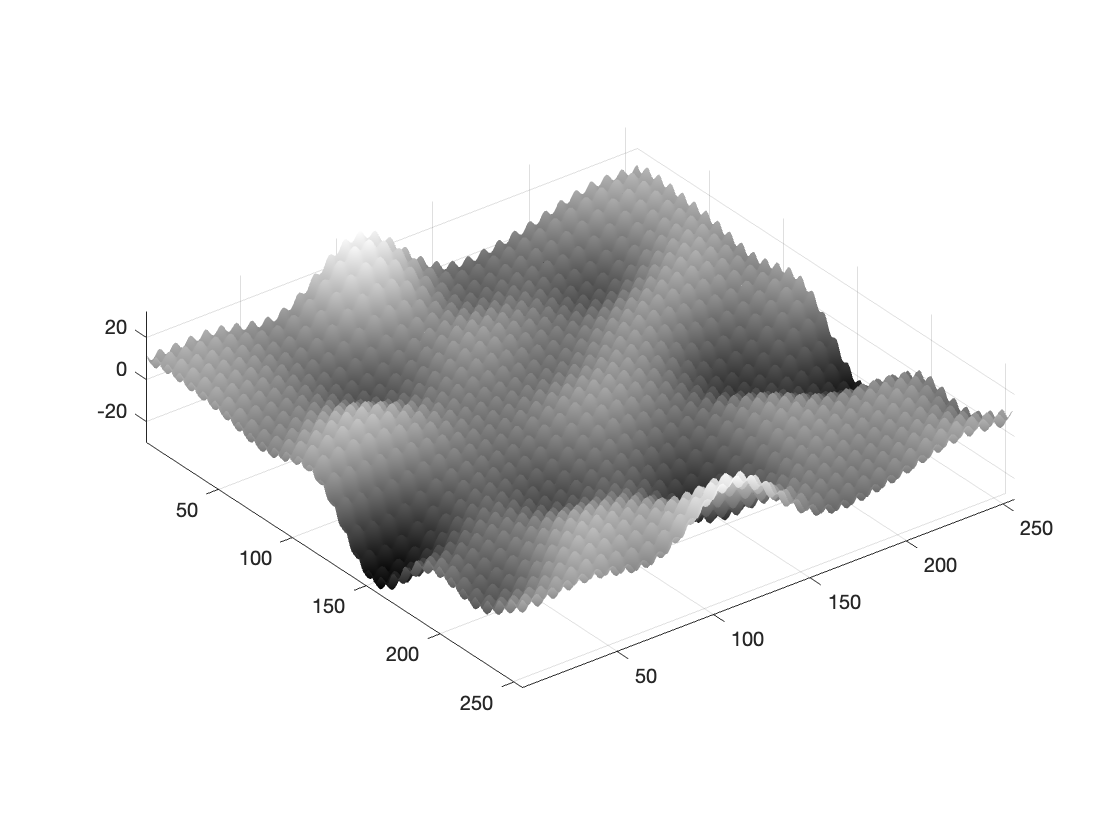


surf(lattice2);
shading interp;
axis equal;
set(gca,"YDir","reverse");
colormap(gray);

Apply the Lawler-Fujita algorithm to deduce the displacement vector. The expected value is, of course, zero displacement at all points.

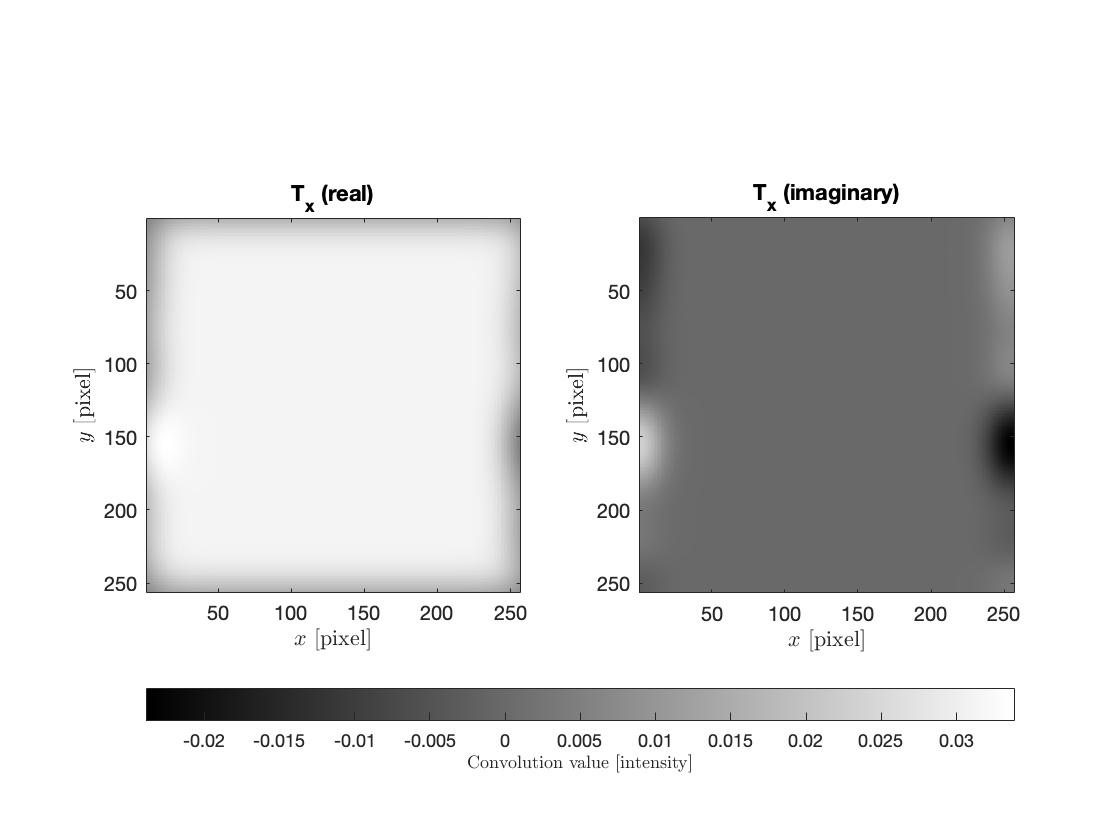

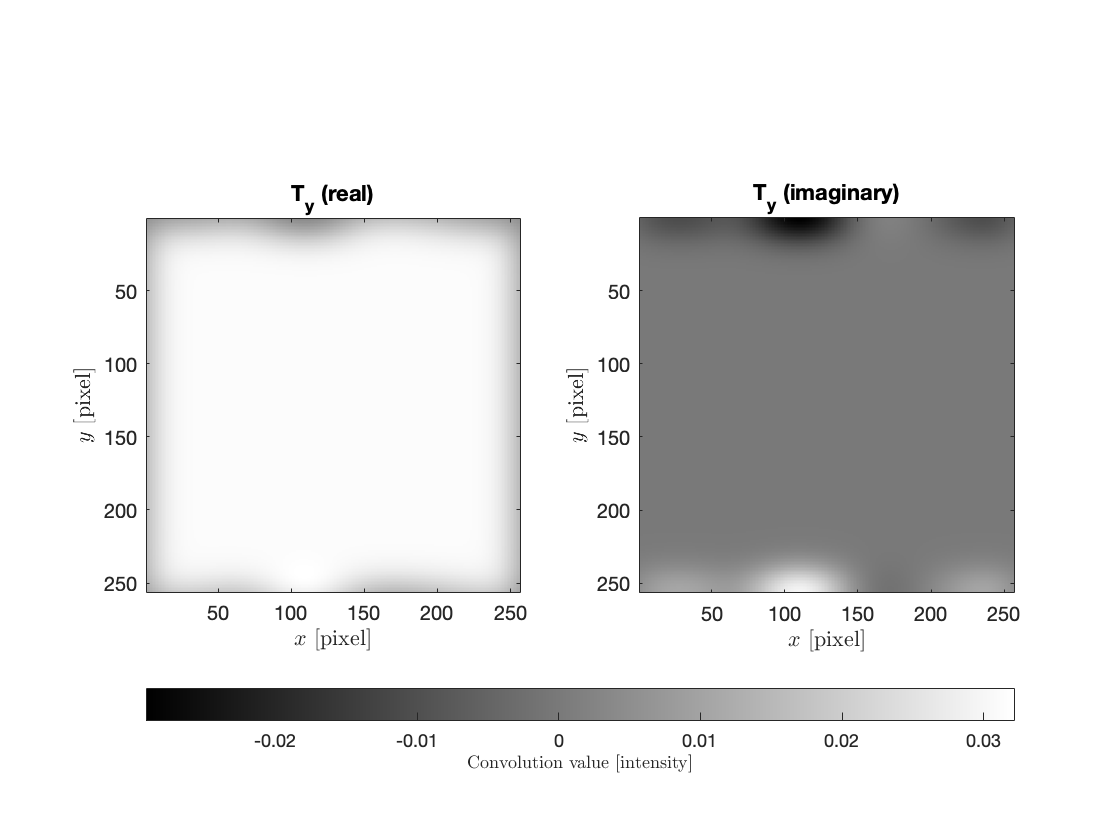

u2 = zeros(image_height,image_length,2);

tic
ucalc = myConv(lattice2,Q_x,Q_y,lambda);

toc

Elapsed time is 0.311322 seconds.


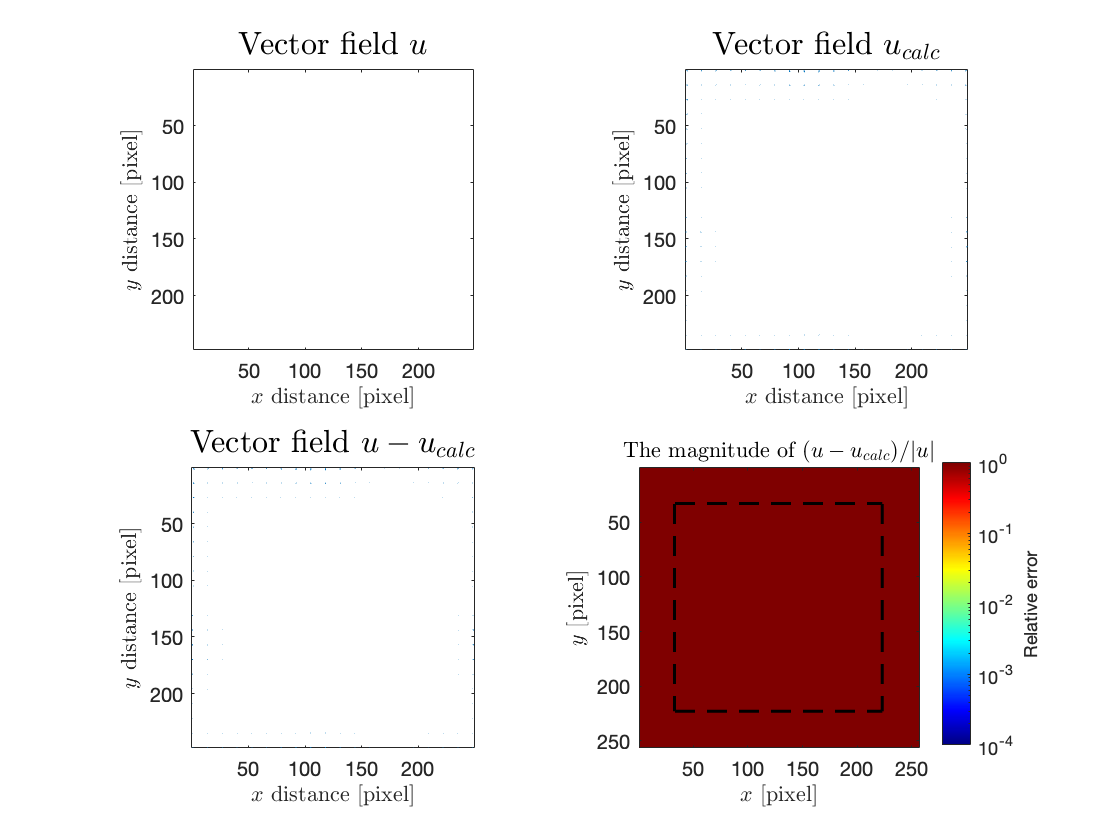


uComboPlot(u2,ucalc,lambda);

The result, at least for the parameters set, is consistent with the expected values.

## Functions

Included here are the list of parameters for every user-defined function in this directory that might be useful in this script.

#### Local

function s = uCreate(h,l,diam,drift,hyst,creep)
    s = zeros(h,l,2);
    
    if nargin<3
        diam = 0;
    end
    
    % define optional parameters
    if ~exist("drift","var") || isempty(drift)
        drift = [0 0];
    end
    if ~exist("hyst","var") || isempty(hyst)
        hyst = [0 0];
    end
    if ~exist("creep","var") || isempty(creep)
        creep = [0 0];
    end
    
    % create x and y for spatial dependence
    [x,y] = meshgrid(1:l,1:h);
    x = x/min(h,l); % normalize the distance
    y = y/min(h,l);
    
    %create t for temporal dependence (like raster scan)
    t = 1:h*l;
    t = reshape(t,[l h])';
    t = t/(h*l); % 1 time unit per l*h pixels (whole image)
    
    % thermal drift
    drift_x = t*drift(1)*diam; % drift in atom diameters
    drift_y = t*drift(2)*diam;
    
    % piezoelectric hysteresis
    hyst_x = (1-exp(-1))*x+exp(-1)-exp(x-1);
    hyst_y = (1-exp(-1))*y+exp(-1)-exp(y-1);
    % maximum displacement by hysteresis in atom diameters
    hyst_x = hyst_x/max(abs(hyst_x),[],"all")*hyst(1)*diam;
    hyst_y = hyst_y/max(abs(hyst_y),[],"all")*hyst(2)*diam;
    % note that the exponent (-1 in this case) could be adjusted to change
    % the behavior of the hysteresis curve
    
    % piezoelectric creep
    creep_x = x.*exp(-t);
    creep_y = y.*exp(-t);
    % maximum displacement by creep in atom diameters
    creep_x = creep_x/max(abs(creep_x),[],"all")*creep(1)*diam;
    creep_y = creep_y/max(abs(creep_y),[],"all")*creep(2)*diam;
    % note that the coefficient of t (-1 in this case) could be adjusted to
    % change the behavior of the creep
    
    % change these to change the vector field u
    s(:,:,1) = drift_x+hyst_x+creep_x;
    s(:,:,2) = drift_y+hyst_y+creep_y;
    
%     if isnan(s)
%         s = zeros(h,l,2);
%     end
% I forgot what this was for
end

#### The big ones

Q = myFFT(P, nm, dip, diam) —* Q is the fft; P is the image; nm is the title; dip=[0.65 1] [optional] sets the limits of the colorbar where 1 is the value of the second highest peak; diam [optional] is the atom diameter which sets the maximum frequency for the low-pass filter*

**(!) **s = uCreate(h,l, scale_mag) —* s is the vector field; h, l are the matrix dimensions; scale_mag=15 [optional] scales the magnitudes of the vectors*

P = uTransform(s,qx,qy) —* P is the image matrixl s is the vector field; qx, qy are the lattice wavevectors*

blat = myConv(lat,qx,qy,lamb) —* blat is the vector field result of the convolution; lat is the image matrix; qx, qy are the lattice wavevectors; lamb is *$\Lambda_u$ in Lawler et al. (2010)'s supplementary information paper

p = noiseLaplace(ny,nx,a) — *p is the output noise; ny, nx are the dimensions of the image; a is the atom radius*

#### Plotting

latticePlot(P0,nm1,r,num) — *P0 is the image (uint8); nm1 is the title; r [optional], num=8 [optional] specify the view*

comboPlot(P0, nm, a) — * P0 is the image (uint8); nm1 is the title; a is the atom diameter*

uPlot(s,nm) —* s is the vector field; nm is the title*

convPlot(lat,nm) —* lat is the image lattice; nm is the title*

uComboPlot(u,ucalc) —* u is the known vector field; ucalc is the calculated vector field*

noisePlot(h,l,z,it,maxf) —* h,l are matrix dimensions; z is *$\Delta$*intensity*;* it [optional] is the number of iterations; maxf [optional] is the maximum frequency*

#### Miscellaneous